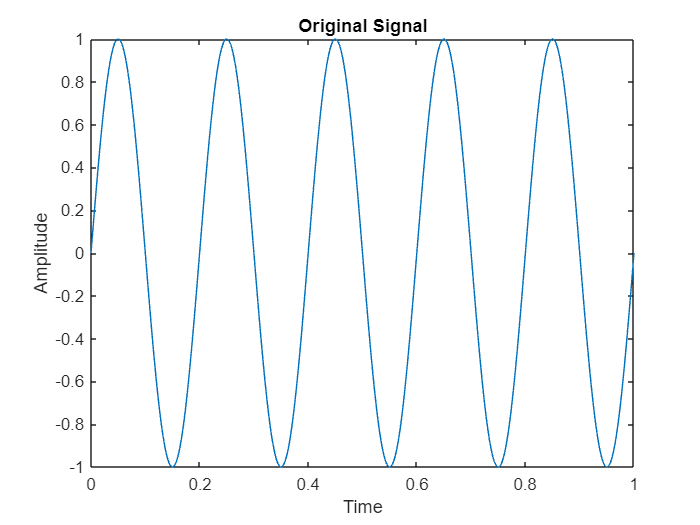

% Sampling and Reconstruction
clc;
clear;
fs=1000;
f=5;
t=0:1/fs:1;
original_sig=sin(2*pi*f*t);
plot(t,original_sig);
xlabel("Time");
ylabel("Amplitude");
title("Original Signal")

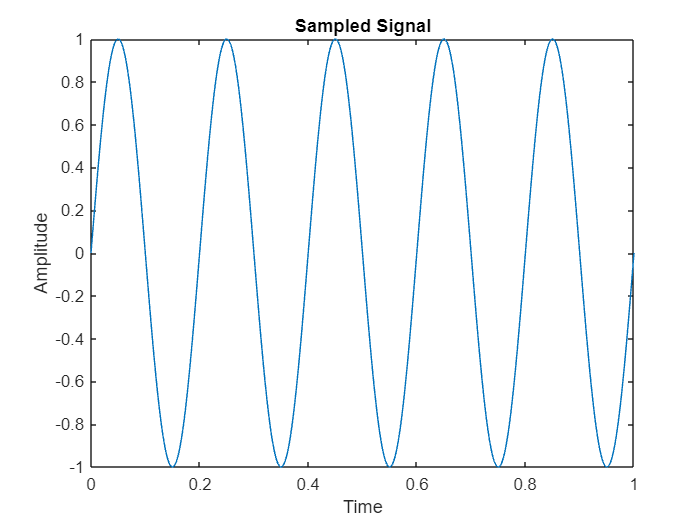

t_discrete=0:1/fs:1;
sampled_sig=sin(2*pi*f*t_discrete);
plot(t,sampled_sig);
xlabel("Time");
ylabel("Amplitude");
title("Sampled Signal")

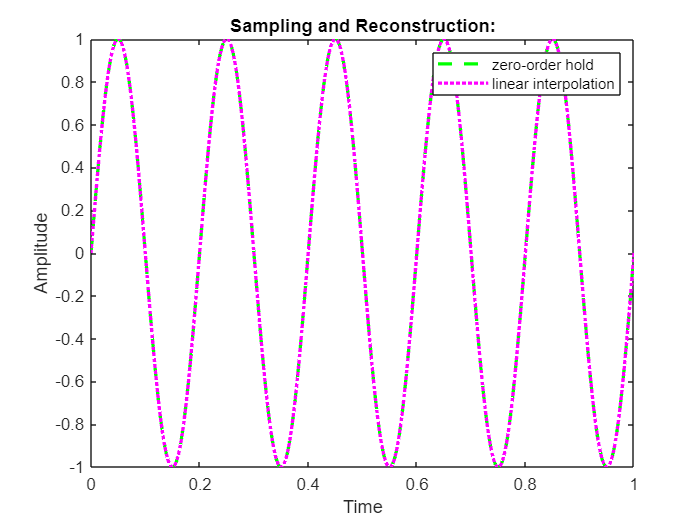

recontructed_zoh=zeros(1,length(t));
for i=1:length(t_discrete)
    index=find(t>=t_discrete(i),1,'first');
    recontructed_zoh(index)=sampled_sig(i);
end
recontructed_linear=interp1(t_discrete,sampled_sig,t,'linear');
plot(t,recontructed_zoh,'g--','LineWidth',2);
hold on;
plot(t,recontructed_linear,'m:','LineWidth',2);
legend('zero-order hold','linear interpolation')
title('Reconstructed signal ')
xlabel('Time')
ylabel('Amplitude')
title('Sampling and Reconstruction:');